# **The *****V*****i*****b*****r*****a*****t*****i*****n*****g***** Cantilever: Modelling the Dynamic Beam Equation**

## Mechanics of Solids and Structures

Ava Lakmazaheri

# I. Introduction

When you apply a load to the free end of a cantilevered beam, it can exhibit some [interesting behavior](https://www.youtube.com/watch?v=6RgJex3EKwk). In this script, we are going to break down what exactly this behavior is and why it occurs. Let's start with a simple description of the system. We are considering an Euler-Bernoulli beam: subjected to only lateral loads and with a resulting deflection that is small compared to the length of the beam. This particular beam will be fixed at one end and have a force applied at the free end, causing vertical deflection *u*.

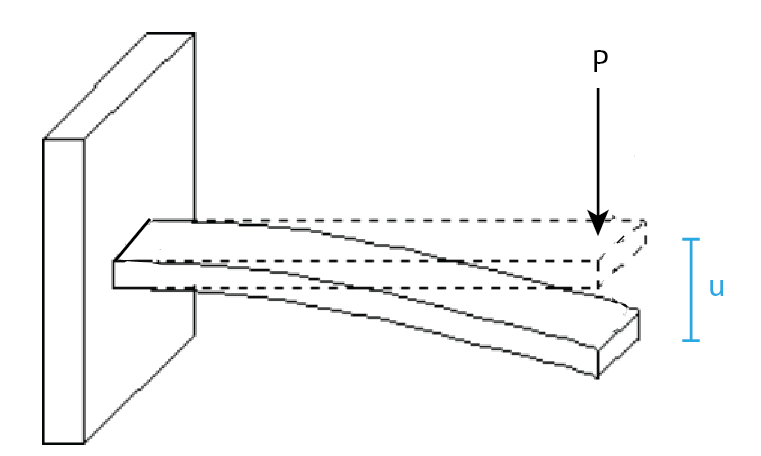

We can describe the entire motion of the beam in terms of *u*. How is this a partial differential equation? Our goal is to relate the variance of *u *in time (a partial derivative with respect to t) and space (a partial derivative with respect to u). Let's get started!

# II. Physical Interpretation

Since we know we are going to be talking about partial derivatives, let's spend some time understanding what they mean physically.

First, recall that we defined ***u ***as vertical displacement. The below figure traces u as a function of space (x).

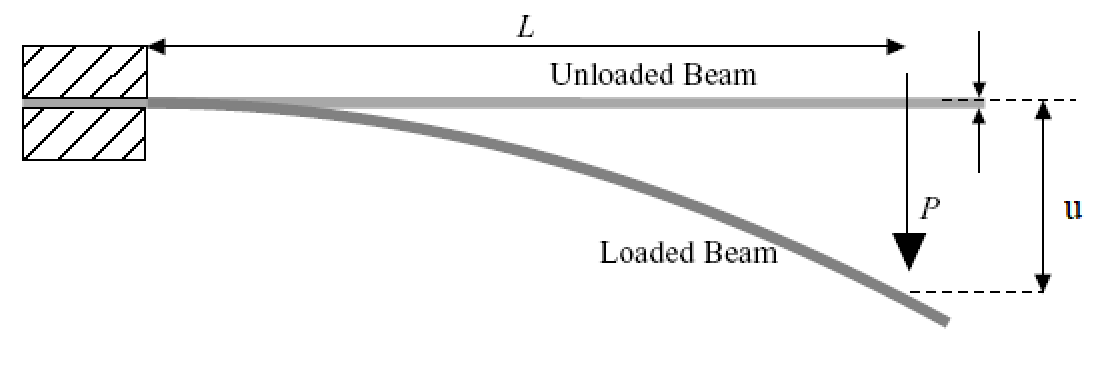

${\mathbf{u}}_{\mathbf{x}} \text{ }$: Slope. As with any function, the first derivative of u gives the slope of the tangent line at the point.

${\mathbf{u}}_{\mathit{\mathbf{xx}}} \text{ }$: Curvature/Bending Moment. In calculus terms, we know that the second derivative of a function describes its curvature. For our beam, the curvature relates directly to the bending moment. Intuitively, this makes sense - the larger the force P placed on the system, the more the beam will bend. But let's dig into the math that gets us here.

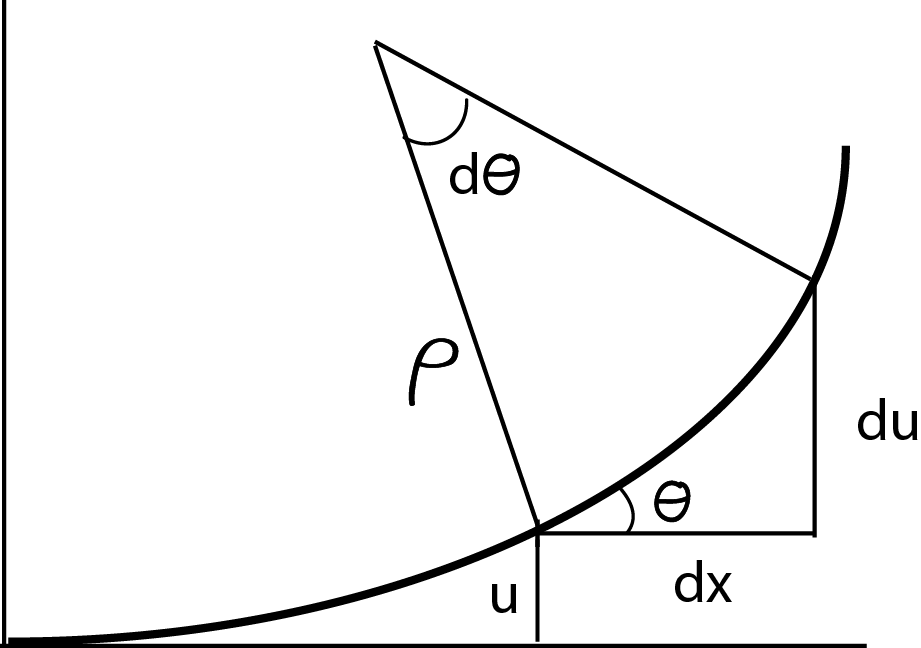

We start with basic geometry. $\mathrm{tan}\left(\theta \right)=\frac{\partial u}{\partial x}$

Take $\frac{\partial }{\partial s}$ of both sides to get ${\mathrm{sec}}^2 \left(\theta \right)\frac{\partial \theta }{\partial s}=\frac{\partial^2 u}{\partial x^2 }\frac{\partial x}{\partial s}$

Rearranging this equation and expanding for cos($\theta$) gives $\frac{\partial \theta }{\partial s}=\frac{\partial^2 u}{\partial x^2 }{\mathrm{cos}}^2 \left(\theta \right)\frac{\partial x}{\partial s}=\frac{\partial^2 u}{\partial x^2 }{\frac{\partial x}{\partial s}}^3$

So $\frac{\partial \theta }{\partial s}$ $\left(=\frac{1}{\rho }\right)$ is equal to $u_{\text{xx}} \text{ }$$\frac{1}{{\left(1+{u_{\mathrm{x}} }^2 \right)}^{\frac{3}{2}} }$

For small displacement $u_{\mathrm{x}}$ << 1, so this expression simplifies to: $\frac{1}{\rho }=u_{\text{xx}} \text{ }$

Next, we write expressions for strain and stress.


$$\varepsilon =\frac{\Delta L}{L}=\frac{\left(\rho -y\right)d\theta \text{ }-\rho d\theta }{\rho d\theta }=-\frac{y}{\rho }=-u_{\mathrm{xx}} y$$
 


$$\sigma =\frac{-y\text{ }M}{I }$$


Now, we can relate these values to find expression for moment in terms of curvature.


$$\sigma =E\varepsilon$$



$$\frac{- y\text{ }M}{I}=-Eu_{\mathrm{xx}} y$$



$$u_{\text{xx}} =\frac{M }{EI }$$


${\mathbf{u}}_{\mathit{\mathbf{\text{xx}}}\mathbf{x}}$:  Shear. This (and higher) spatial derivatives become less physically intuitive. Even so, let us try to picture how the moment ($u_{xx}$) is changing over space as how sharply the beam is twisting out of the plane of curvature.


$$V=\frac{\partial M}{\partial x}=\mathrm{EI}u_{\mathrm{xxx}}$$


# III. Deriving the Beam Equation: Euler-Lagrange to Euler-Bernoulli

The Euler-Lagrange equation is a second-order PDE whose solutions minimize or maximize a given functional (e.g., energy, distance). For this system:


$$\text{ℒ}\left(x,t,u,u_t ,u_{\mathrm{xx}} \right):=\rho A{u_t }^2 -{\frac{\mathrm{EI}}{2}u_{\mathrm{xx}} }^2$$



$$\frac{\mathrm{dℒ}}{\mathrm{du}}-\frac{d}{\mathrm{dt}}\frac{\mathrm{dℒ}}{du_t }+\frac{d^2 }{{\mathrm{dx}}^2 }\frac{\mathrm{dℒ}}{du_{\mathrm{xx}} }=0$$


The general description for$\frac{\text{dℒ}}{du_{\text{xx}} }$ is the distributed load on the beam. Since the system we are considering is in free vibration, this equals zero.


$$\frac{\text{dℒ}}{\text{du}}=0$$
 


$$\frac{\text{dℒ}}{du_t }=\rho Au_t$$



$$\frac{\text{dℒ}}{du_{\mathrm{xx}} }=-\mathrm{EI}u_{\mathrm{xx}}$$


Substituting these values into the Euler-Lagrange equation, we get the beam equation.


$$-\rho Au_{\mathrm{tt}} -\mathrm{EI}u_{\mathrm{xxxx}} =0$$



$$u_{\text{tt}} =-\frac{\text{EI}}{\rho A}u_{\text{xxxx}}$$


# IV. Solving the Beam Equation

Solving the beam equation in two dimensions means finding a function u(t,x) that satisfies $u_{\text{tt}} =-\frac{\text{EI}}{\rho A}u_{\text{xxxx}}$. 

To do this, we will use a trick called separation of variables to turn our PDE into two ODEs. This involves breaking one function (which depends on time and space) into two which depend on either only time or only space: u = T(t) X(x). When we plug this form into the beam equation, we get:


$$\text{T''}X=-\frac{\text{EI}}{\rho A}T\text{X''''}$$


Since these two functions of time and space are equivalent everywhere, they must both be equal to the same constant. For ease of use later on, we will call this constant ${-\beta }^4$.


$$\frac{1}{T}\text{T''}=-\frac{\text{EI}}{\rho A}\frac{1}{X}\text{X''''}=-\beta^4 \text{ }$$


## Part I. The Space Relation

Let us first attempt to solve for X(x). We can rewrite the equation above as:


$$-\frac{\text{EI}}{\rho A}\frac{1}{X}\text{X''''}=-\beta^4$$



$$\text{X''''}-\frac{\rho A}{\text{EI}}\beta^4 X=0$$


This $\frac{\rho A}{\text{EI}}$ is a little distracting, but if you think of the ODE $\text{X''''}-\beta^4 X=0$, you should be able to see that$X\left(x\right)=\mathrm{cos}\left(\beta x\right)$ and$X\left(x\right)=\mathrm{sin}\left(\beta x\right)$ are both solutions. If you recall the trigonemtric properties of hyperbolic functions, you will also see that $X\left(x\right)=\cos h\left(\beta x\right)$ and $X\left(x\right)=\text{s}\mathrm{inh}\left(\beta x\right)$ are solutions! For reference, these properties are: $\frac{\partial }{\partial x}\mathrm{cosh}\left(x\right)=\mathrm{sinh}\left(x\right)$ and $\frac{\partial }{\partial x}\text{s}\mathrm{in}\text{h}\left(x\right)=\mathrm{cos}\text{h}\left(x\right)$.

Now, don't forget about the $\frac{\rho A}{\text{EI}}$! To account for this constant term, all we have to do is say that $\beta$ is quantized as ${\left(\frac{\rho A}{\text{EI}}\right)}^{\frac{1}{4}}$. 

The general solution to X(x) is a linear combination of its particular solutions. Thus, we can write:


$$X\left(x\right)=\text{ }C_1 \cos \left(\beta x\right)+C_2 \sin \left(\beta x\right)+C_3 \cos h\left(\beta x\right)+C_4 \sin h\left(\beta x\right)$$


Since having four unknowns in our solution is less than ideal, we will now turn to boundary values.

## Part I.A. Boundary Value Problem

We can use a physical interpretation of our system to define spatial boundary conditions. In this notebook, we are considering a cantilevered beam. At the pinned end (x = 0), there can be no vertical displacement or slope. At the free end (x = L), there is no moment or shear force on the cross-section. These conditions can be written as:


$$u \left(0,t\right)=0$$
        
$$u_{\mathrm{xx}} \left(L,t\right)=0$$
    


$$u_x \left(0,t\right)=0$$
        
$$u_{\mathrm{xxx}} \left(L,t\right)=0$$


Note that we can expand this for the space relation alone, as boundary values are independent of time.

$X\left(x\right)=\text{ }C_1 \cos \left(\beta x\right)+C_2 \sin \left(\beta x\right)+C_3 \cos h\left(\beta x\right)+C_4 \sin h\left(\beta x\right)=0$                  :      $X\left(0\right)\text{ }=0\text{   }\longrightarrow \text{  }C_1 =-C_3$

$X\text{'}\left(x\right)=\text{ }{\beta C}_1 \sin \left(\beta x\right)+{\beta C}_2 \cos \left(\beta x\right)+{\beta C}_3 \sinh \left(\beta x\right)+{\beta C}_4 \cosh \left(\beta x\right)=0$        :      $\mathrm{X'}\left(0\right)\text{ }=\text{ }0\text{ }\longrightarrow C_2 =-C_4$

$\mathrm{X}\text{''}\left(x\right)=\text{ }{-\beta^2 C}_1 \left\lbrack \cos \left(\beta x\right)+\beta^2 \mathrm{cosh}\left(\beta x\right)\right\rbrack {-\beta }^2 C_2 \left\lbrack \mathrm{sin}\left(\beta x\right)+\mathrm{sinh}\left(\beta x\right)\right\rbrack =0$      :      $\mathrm{X''}\left(L\right)=\text{ }0\longrightarrow C_2 =C_1 \frac{-\cos \left(\beta L\right)-\mathrm{cosh}\left(\beta L\right)}{\sin \left(\beta L\right)+\mathrm{sinh}\left(\beta L\right)}$$\mathrm{X'''}\left(x\right)={\beta^3 C}_1 \left\lbrack \mathrm{sin}\left(\beta x\right)-\mathrm{sinh}\left(\beta x\right)\right\rbrack {-\beta }^3 C_2 \left\lbrack \mathrm{cos}\left(\beta x\right)+\mathrm{cosh}\left(\beta x\right)\right\rbrack =0$            :     $\mathrm{X'''}\left(L\right)\text{ }=\text{ }0\longrightarrow \cos \left(\beta L\right)\cosh \left(\beta L\right)=-1$

Finally, we can rewrite our spatial relation as shown below. Note that $\beta$ is found by numerically solving $\mathrm{cos}\left(\beta L\right)\mathrm{cosh}\left(\beta L\right)=-1$.


$$X\left(x\right)=C_1 \left\lbrack \cos \left(\beta x\right)-\cos h\left(\beta x\right)+\frac{-\cos \left(\beta L\right)-\mathrm{cosh}\left(\beta L\right)}{\sin \left(\beta L\right)+\mathrm{sinh}\left(\beta L\right)}\left(\mathrm{sin}\left(\beta x\right)-\mathrm{sinh}\left(\beta x\right)\right)\right\rbrack$$


## Part II. The Time Relation

Now let us address the other part of separation of variables: T(t).


$$\frac{1}{T}\text{T''}={-\beta }^4$$



$$\text{T''}+\beta^4 T=0$$


Just as we did above, notice that $T\left(t\right)=\cos \left(\beta^2 t\right)$ and$T\left(t\right)=\text{s}\mathrm{in}\left(\beta^2 t\right)$both satisfy this equation. The general solution of T(t) is a linear combination of these.

 
$$T\left(t\right)=\text{ }A \cos \left(\beta^2 t\right)+B \sin \left(\beta^2 t\right)$$


How do we find these coefficients? What information do we have about the system beahvior in time? Typically, we know the initial conditions u(t = 0,x).

## Part II.A. Initial Conditions

For the sake of this notebook, we will say that the system is at rest at t = 0, but is displaced from equilibrium (this is why it will vibrate at t > 0).


$$u\left(0,x\right)=\phi \left(x\right)$$



$$u_t \left(0,x\right)=0$$


*Finding *$\phi$:

Given the system described at the introduction, we known that the moment $M\left(x\right)=-\mathrm{Px}$, such that the moment equals zero at the fixed end and PL at the free end. We also know from Section II that $u_{\mathrm{xx}} =\frac{M\left(x\right)}{\mathrm{EI}}$. Thus, we can expand M(x) and integrate twice to evalute the vertical displacement as a function of length: $u\left(0,x\right)=\frac{Px^3 }{6\mathrm{EI}}$


$$u\left(t,x\right)={\left(\mathrm{Acos}\left(\beta^2 t\right)+B \sin \left(\beta^2 t\right)\right)} X\left(x\right)$$



$$u\left(0,x\right)\text{ }=A\text{ }X\left(x\right)=\frac{Px^3 }{6\mathrm{EI}}$$



$$u_t \left(0,x\right)\text{ }=\beta^2 B\text{ }X\left(x\right)$$
 
$$\longrightarrow B=0$$
 

Solving for the A as a Fourier coefficient,


$$A=\frac{2}{L}\int_0^L u\left(0,x\right)X\left(x\right)\mathrm{dx}$$



$$A=\frac{2}{L}\int_0^L \frac{Px^3 }{6\mathrm{EI}}\left\lbrack \cos \left(\beta x\right)-\cos h\left(\beta x\right)+\frac{-\cos \left(\beta L\right)-\mathrm{cosh}\left(\beta L\right)}{\sin \left(\beta L\right)+\mathrm{sinh}\left(\beta L\right)}\left(\mathrm{sin}\left(\beta x\right)-\mathrm{sinh}\left(\beta x\right)\right)\right\rbrack \text{dx}$$


This is a relatively involved equation, but we can solve for it (see code below) and thus get A only in terms of known terms P, L, E, and I.

Finally*,* we have a complete representation for the motion of this cantilevered beam.


$$u\left(t,x\right)=\text{Acos}\left(\beta^2 t\right)\left\lbrack \cos \left(\beta x\right)-\cos h\left(\beta x\right)+\frac{-\cos \left(\beta L\right)-\cosh \left(\beta L\right)}{\sin \left(\beta L\right)+\sinh \left(\beta L\right)}\left(\sin \left(\beta x\right)-\sinh \left(\beta x\right)\right)\right\rbrack$$


# V. Modelling & Visualization

## Behavior in Space

% Beam and material properties
L = 1;
P = 50;
W = 0.05;
Th = 0.006;
A = W*Th;
V = L*W*Th;
Ix = (1/12)*W*Th^3;
E = 69.90e+9;
Ro = 2770;

% Number of vibration modes to consider
nmodes = 5;
nnodes = 3*nmodes;
n = 1;
    
% Numerically solve for beta
while n <= nnodes
 betaL(n)=fzero(@(betaL)cosh(betaL)*cos(betaL)+1,[n n+3]);
 n = n+3; 
end
beta = betaL(betaL~=0)/L'

beta =     1.8751    4.6941    7.8548   10.9955   14.1372


n = 1;
wn = ones(1,nmodes);
fn = ones(1,nmodes);

for n = 1:nmodes
    % Natural (angular) frequencies for each mode n
    wn(n)= beta(n)^2*sqrt((E*Ix)/(Ro*A));
    
    % Natural (temporal) frequencies for each mode n
    fn(n)= wn(n)/(2*pi);
end

wn

wn =    1.0e+03 *

    0.0306    0.1917    0.5368    1.0519    1.7389


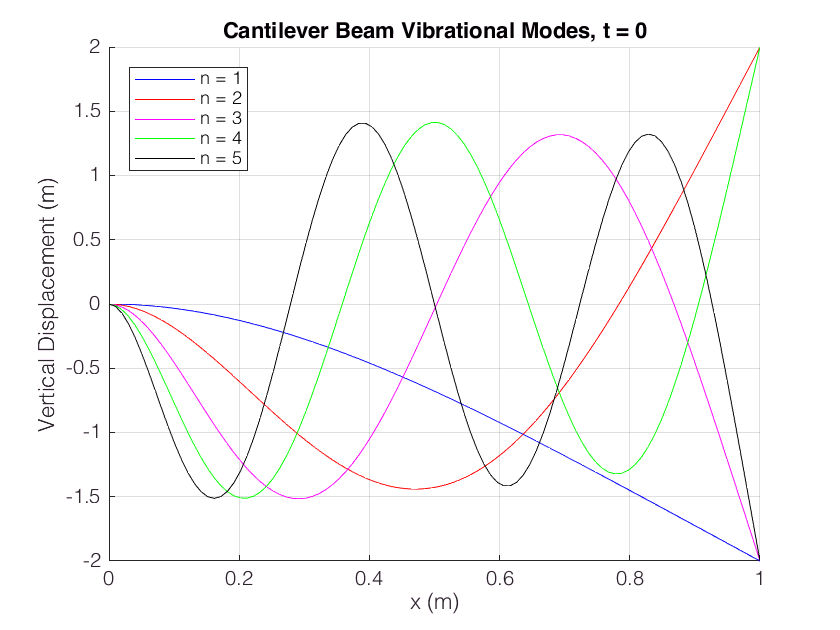

% BVP
frac = zeros(1, nmodes);
for n = 1:nmodes
    frac(n)= (-cos(beta(n)*L) - cosh(beta(n)*L)) / (sin(beta(n)*L) + sinh(beta(n)*L));
end

% Solve for X(x) over beam length
x_size = 100;
x = linspace(0, L, x_size);
X = zeros(nmodes,length(x));
Xtemp = '(cos(beta(n).*x(i)) - cosh(beta(n).*x(i))) + frac(n).*(sin(beta(n).*x(i)) - sinh(beta(n)*x(i)))';
for n = 1:nmodes
    for i=1:length(x)
        X(n,i) = eval(Xtemp);
    end
end

% Plot first five modes of beam vibration in space
figure; hold on;
plot(x, X(1,:), 'b-')
plot(x, X(2,:), 'r-')
plot(x, X(3,:), 'm-')
plot(x, X(4,:), 'g-')
plot(x, X(5,:), 'k-')
grid
title('Cantilever Beam Vibrational Modes, t = 0')
legend('n = 1', 'n = 2', 'n = 3', 'n = 4', 'n = 5', 'Location', 'northwest')
xlabel('x (m)'); ylabel('Vertical Displacement (m)')

## Behavior over Time

t_max = 100;
t_size = x_size;
t_all = linspace(0, t_max, t_size);
T = zeros(nmodes,t_size);

% Initial conditions
A = zeros(1, nmodes);
for n = 1:nmodes
    fun = @(x) ((P*x.^3)/(6*E*Ix)) .* (cos(beta(n)*x) - cosh(beta(n)*x) + frac(n)*(sin(beta(n)*x) - sinh(beta(n)*x)));
    A(n) = integral(fun,0,L);
end
       
% Plug in beta to general T(t) expression
for n = 1:nmodes
    for i = 1:t_size
        t = t_all(i);
        T(n, i) = A(n)*cos(beta(n)^2 * t) +  0*sin(beta(n)^2 * t);
    end
end

% Evaluate u(t,x) = T(t)*X(x) at each point in space and time
spacetime = [];
for i = 1:t_size
    t = t_all(i);
    sum = zeros(1,length(x));
    for n = 1:nmodes
        sum = sum + X(n,:) * T(n,i);
    end
    spacetime = [spacetime;sum];
end

## Visualize: Animation

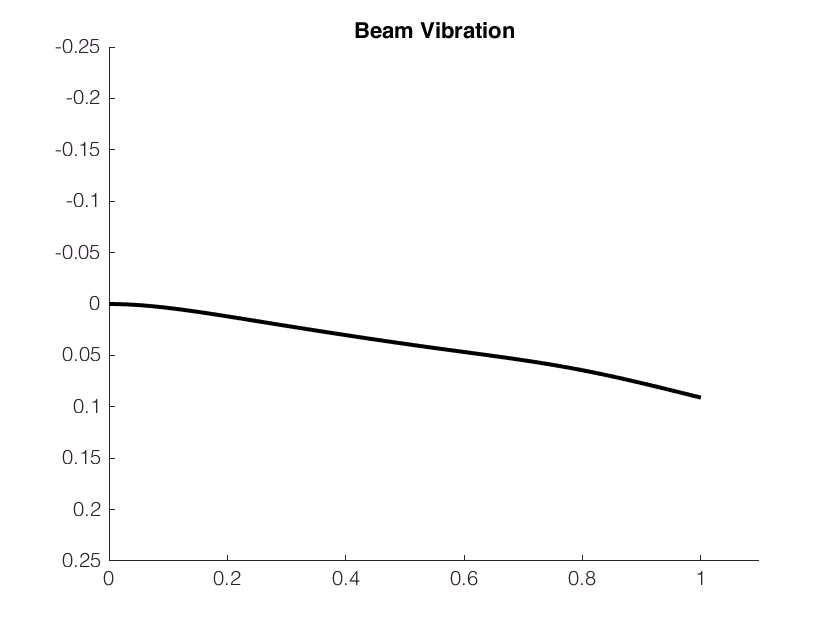

% Unfortunately, MATLAB live scripts do not support animations. To visualize the beam's behavior over time, open a new figure
% SELECT AND RUN WITH F9
figure;
h3 = axes('YDir','reverse');
title('Beam Vibration')
hold on;
axis([0 1.1 -0.25 0.25])
L = plot(x, zeros(length(x)));
for t = 1:t_max
    set(L,'Ydata',spacetime(t,:), 'LineWidth', 2, 'Color', 'k');
    pause(.05)
end

## Visualize: 3D Plot

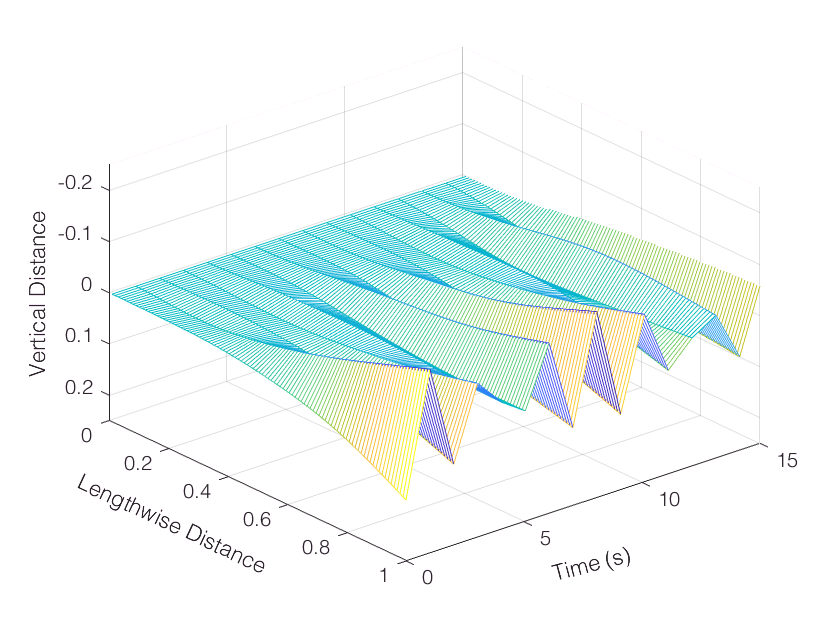

figure;
axes('ZDir','reverse');
axis([0 1 0 15 -0.25 0.25]);
hold on
[Xax,Yax] = meshgrid(x(1,2:end),t_all);
mesh(Xax,Yax,spacetime(:,2:end))
xlabel('Lengthwise Distance','Rotation',-25)
ylabel('Time (s)','Rotation',15)
zlabel('Vertical Distance')
view(60,30)
grid on

view([50.00 35.60])